# Inizializzazione del programma

clear all;
close all;
clc;
Group_name = 'GruppoG';

# Inizializzazione del Sistema

%addpath('C:\Users\edoar\Documenti\git hub\Progetto_LAB_Automatica')
model=ElasticRoboticSystem();
model.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000



% visualizzazione output del sistema
output_number=model.getOutputNumber 

output_number = 4

for i=1:output_number
    fprintf('Output %d:    %s\n',i,model.getOutputName{i});
end

Output 1:    position_1
Output 2:    position_2
Output 3:    velocity_1
Output 4:    velocity_2



% visualizzazione sampling time
st=model.getSamplingPeriod;

# Risposta in frequenza del sistema

## Controllore in cascata di base per l'identificazione in close-loop

% sistema + controllore
cs=ControlledSystemScara(model,Group_name);
% controllo del giunto 1
Kp_g1 = 0.1;
Ki_g1 = 0.1;
% controllo del giunto 2
Kp_g2 = 0.01;
Ki_g2 = 0.1;
ctrl = ScaraBasicPIController(st, Kp_g1, Ki_g1, Kp_g2, Ki_g2);

% impostazione della coppia massima
ctrl.setUMax(model.getUMax);

% impostazione della isatanza del controllore
cs.setController(ctrl);

## Segnale di eccitazione

la durata del segnale dovrebbe essere al meno un periodo 

#### Portante

% parametri del segnale di eccitazione
omega_portante = 1;     %[rad/s]
ampiezza_portante= 250;   %[Nm]
T_portante=2*pi/omega_portante;            %[s]
%vettore tempo (> T_portante)
t=(0:st:(1.1*T_portante))';

portante=ampiezza_portante*sin(omega_portante*t);

#### Chirp

ampliezza_identificazione= 250;%[Nm]
% frequenza minima
w0=omega_portante*10; %[rad/s]
% frequenza massima
w1=pi/st; %[rad/s]

control_action_identificazione = ampliezza_identificazione*chirp(t,w0/2/pi,t(end),w1/2/pi,'logarithmic');

#### segnale di eccitazione = portante + chirp

control_action = portante + control_action_identificazione;
%riferimento
reference = zeros(length(t),model.getOutputNumber);

#### giunto 1

% creazione del segnale di eccitazione al giunto 1
exciting_signal_g1 = zeros(length(t),model.getInputNumber);
exciting_signal_g1(:,1) = control_action;
cs.initialize;
% applico il segnale di eccitazione al giunto 1
for idx=1:length(t)
    [process_output_g1(idx,:),control_action_g1(idx,:),t_g1(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g1(idx,:)');  
end
% modello giunto 1
identification_g1 = iddata(process_output_g1(:,3),control_action_g1(:,1),st);
frequency_response_identification_g1 = spafdr(identification_g1);

#### giunto 2

% creazione del segnale di eccitazione al giunto 2
exciting_signal_g2 = zeros(length(t),model.getInputNumber);
exciting_signal_g2(:,2) = control_action;
cs.initialize;
% applico il segnale di eccitazione al giunto 2
for idx=1:length(t)
    [process_output_g2(idx,:),control_action_g2(idx,:),t_g2(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g2(idx,:)');  
end
% modello giunto 2
identification_g2 = iddata(process_output_g2(:,4),control_action_g2(:,2),st);
frequency_response_identification_g2 = spafdr(identification_g2);

# Identificazione come sistemi al terzo ordine

ordine_sistema_3 = 3;

### Giunto 1

weight1_1 = 100;
weight1_2 = 1000;

peso = ones(length(frequency_response_identification_g1.Frequency),1);
peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3;   

Stima dei modelli continuo e discreto del primo giunto.

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_g13 = ssest(frequency_response_identification_g1, ordine_sistema_3, opts);
modello_discreto_g13 = ssest(frequency_response_identification_g1, ordine_sistema_3, 'Ts', st, opts);

Confronto con la risposta in frequenza del primo giunto.

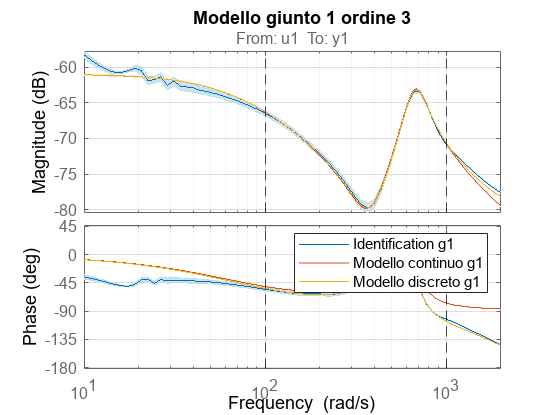

figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on

showConfidence(h,3)
bode(modello_continuo_g13,modello_discreto_g13, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')

hold off
grid on
xlim([weight1_1/10 weight1_2*2])

legend('Identification g1','Modello continuo g1','Modello discreto g1')
title('Modello giunto 1 ordine 3')

### Giunto 2

weight2_1 = 250;
weight2_2 = 1000;

peso = ones(length(frequency_response_identification_g2.Frequency),1);
peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

Stima dei modelli continuo e discreto del secondo giunto.

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_g23 = ssest(frequency_response_identification_g2,3,opts);
modello_discreto_g23 = ssest(frequency_response_identification_g2,3,'Ts',st,opts);

Confronto con la risposta in frequenza del secondo giunto

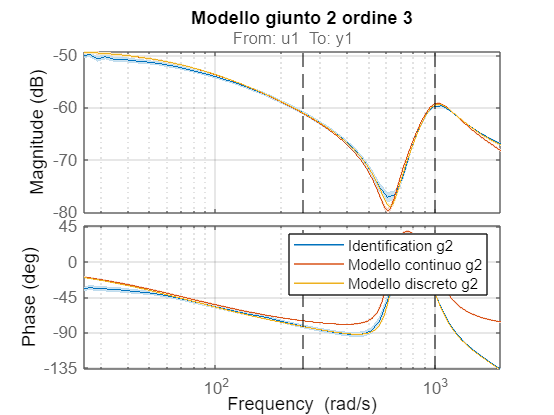

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

h=bodeplot(frequency_response_identification_g2, bode_opts);

hold on
showConfidence(h,3)
bode(modello_continuo_g23,modello_discreto_g23, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')

hold off
grid on
xlim([weight2_1/10 weight2_2*2])

legend('Identification g2','Modello continuo g2','Modello discreto g2')
title('Modello giunto 2 ordine 3')

# Tutti e due al quinto ordine

Stima dei modelli al quinto ordine a partire dai risultati ottenuti sui due giunti.

ordine_sistema_5 = 5;

### Giunto 1

weight1_1 = 100;
weight1_2 = 1000;

peso = ones(length(frequency_response_identification_g1.Frequency),1);
peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3;   

Stima dei modelli continuo e discreto del primo giunto.

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_g15 = ssest(frequency_response_identification_g1, ordine_sistema_5, opts);
modello_discreto_g15 = ssest(frequency_response_identification_g1, ordine_sistema_5, 'Ts', st, opts);

Confronto con la risposta in frequenza del primo giunto.

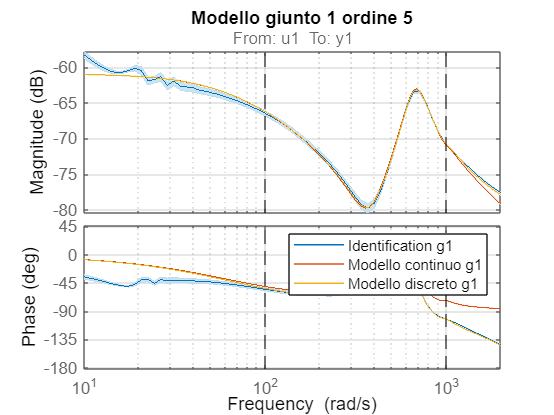

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g15,modello_discreto_g15, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')

hold off
grid on
xlim([weight1_1/10 weight1_2*2])

legend('Identification g1','Modello continuo g1','Modello discreto g1')
title('Modello giunto 1 ordine 5')

### Giunto 2

weight2_1 = 250;
weight2_2 = 1000;

peso = ones(length(frequency_response_identification_g2.Frequency),1);
peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

Stima dei modelli continuo e discreto del secondo giunto.

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_g25 = ssest(frequency_response_identification_g2,5,opts);
modello_discreto_g25 = ssest(frequency_response_identification_g2,5,'Ts',st,opts); 

Confronto con la risposta in frequenza del secondo giunto

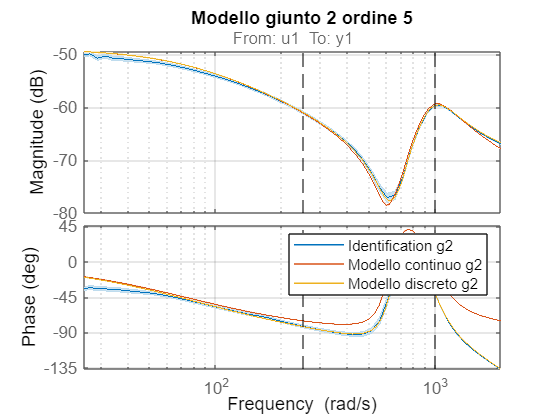

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g25,modello_discreto_g25, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')

hold off
grid on
xlim([weight2_1/10 weight2_2*2])

legend('Identification g2','Modello continuo g2','Modello discreto g2')
title('Modello giunto 2 ordine 5')

#### Confronto modelli giunto 1

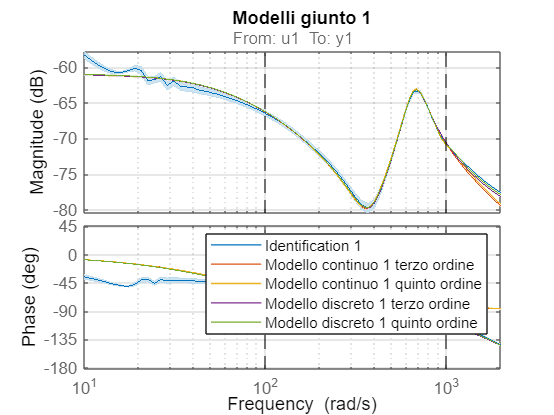

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g1, bode_opts);
hold on

showConfidence(h,3)
bode(modello_continuo_g13,modello_continuo_g15,modello_discreto_g13,modello_discreto_g15, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
hold off

grid on
xlim([weight1_1/10 weight1_2*2])

legend('Identification 1','Modello continuo 1 terzo ordine','Modello continuo 1 quinto ordine','Modello discreto 1 terzo ordine','Modello discreto 1 quinto ordine')
title('Modelli giunto 1')

#### Confronto modelli giunto 2

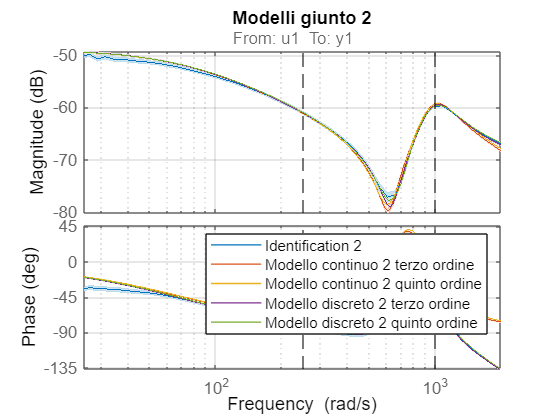

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on

showConfidence(h,3)
bode(modello_continuo_g23,modello_continuo_g25,modello_discreto_g23,modello_discreto_g25, bode_opts)

h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
hold off

grid on
xlim([weight2_1/10 weight2_2*2])

legend('Identification 2','Modello continuo 2 terzo ordine','Modello continuo 2 quinto ordine','Modello discreto 2 terzo ordine','Modello discreto 2 quinto ordine')
title('Modelli giunto 2')